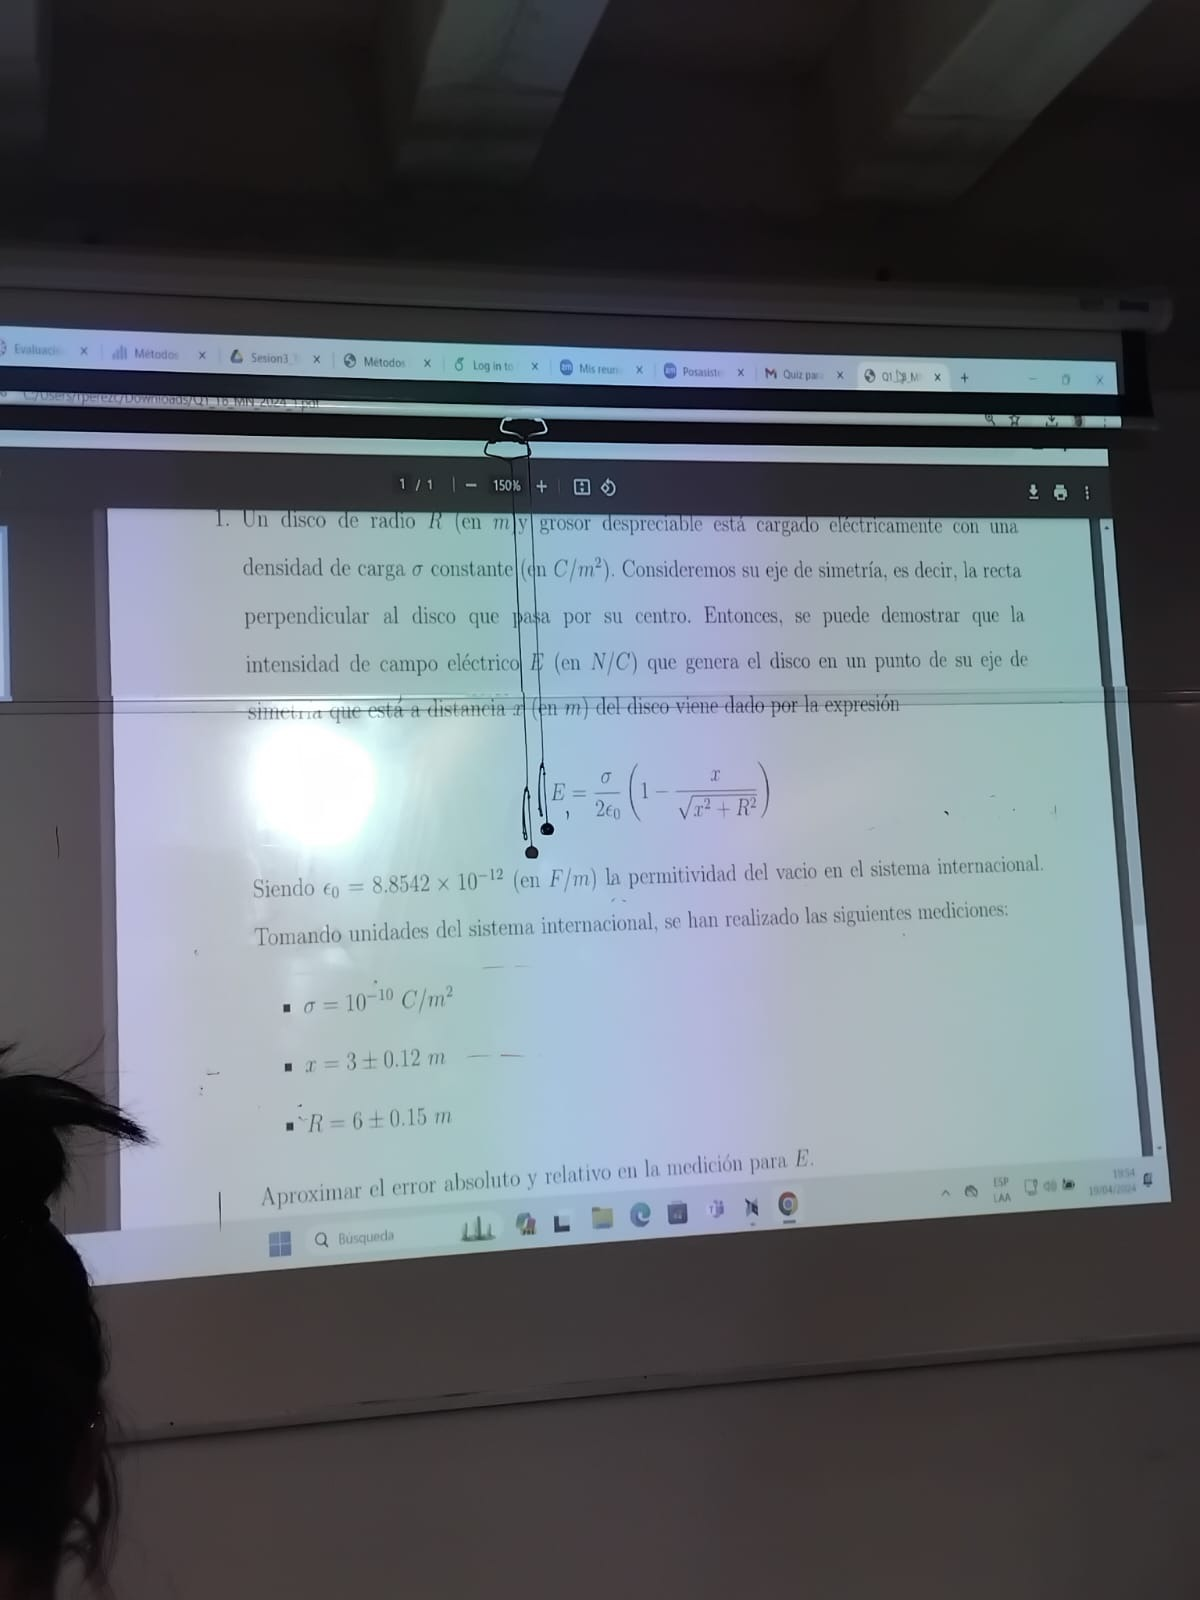

syms x R

a = 10^(-10);
e = 8.8542 * 10 ^(-12);

E = @(x,R) (a/2*e)*(1 - x/(sqrt(x^2 + R^2)))

E = function_handle with value:
    @(x,R)(a/2*e)*(1-x/(sqrt(x^2+R^2)))


x_val = 3;
R_val = 6;

eax = 0.12;
eaR = 0.15;

dE_dx = matlabFunction(diff(E,x))

dE_dx = function_handle with value:
    @(R,x)1.0./sqrt(R.^2+x.^2).*(-4.4271e-22)+x.^2.*1.0./(R.^2+x.^2).^(3.0./2.0).*4.4271e-22


dE_dR = matlabFunction(diff(E,R))

dE_dR = function_handle with value:
    @(R,x)R.*x.*1.0./(R.^2+x.^2).^(3.0./2.0).*4.4271e-22



eaE = abs(dE_dx(R_val,x_val)) * eax + abs(dE_dR(R_val,x_val)) * eaR

eaE = 1.0295e-23


valorExacto = E(x_val,R_val)

valorExacto = 2.4472e-22


-erE = eaE/valorExacto

erE = 0.0421